clear
close all
I = imread('lena_std.tif');

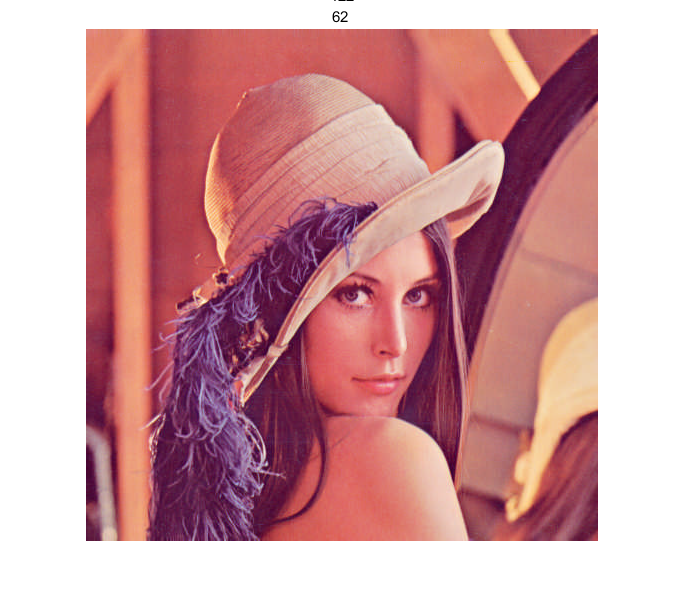

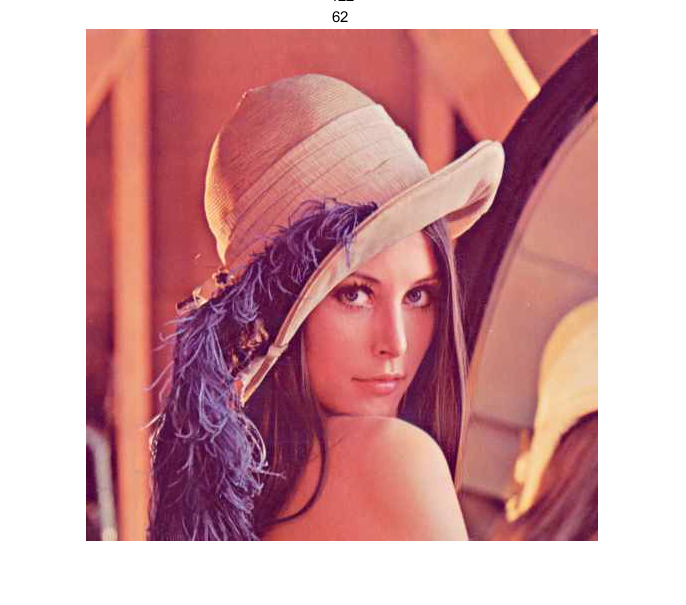

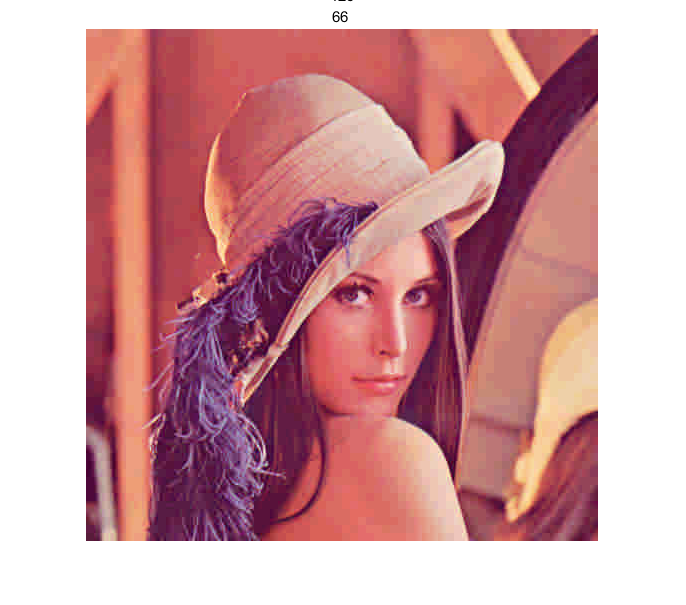

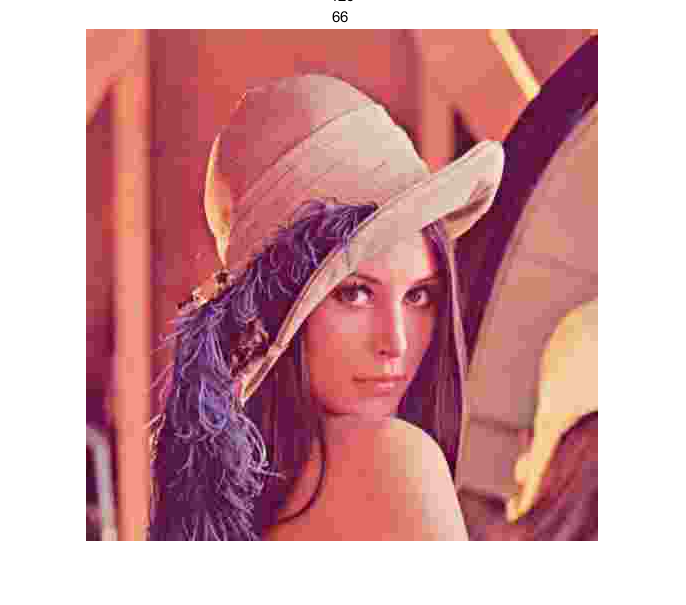

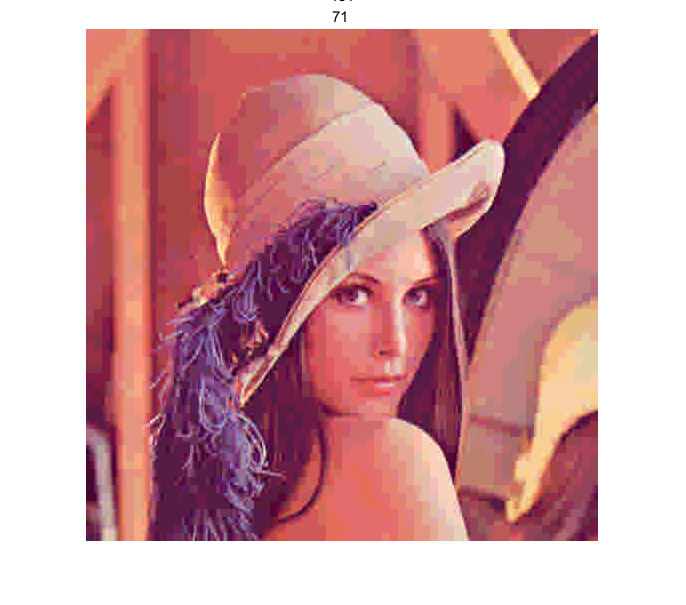

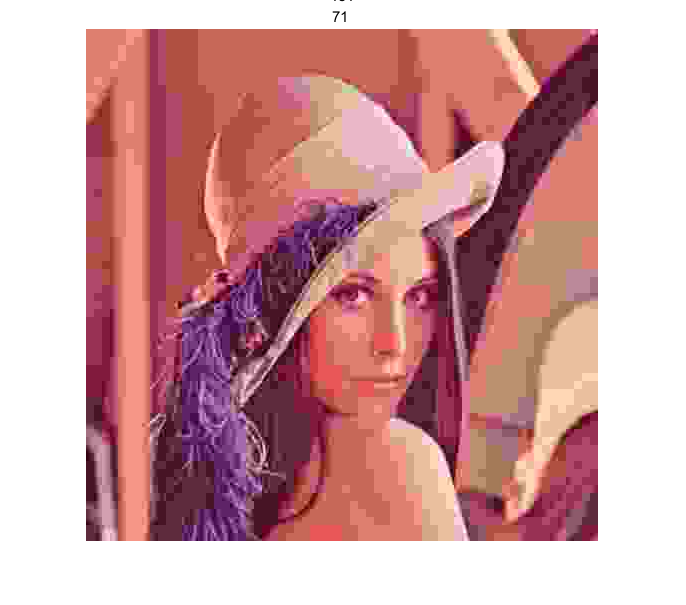

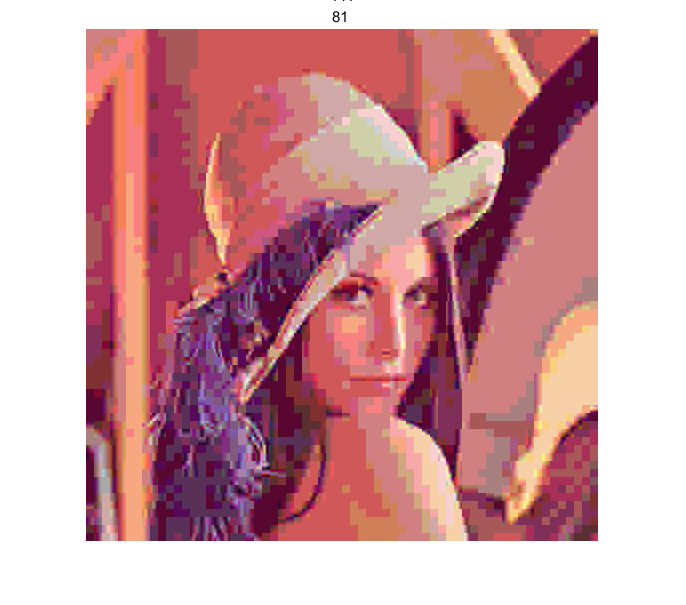

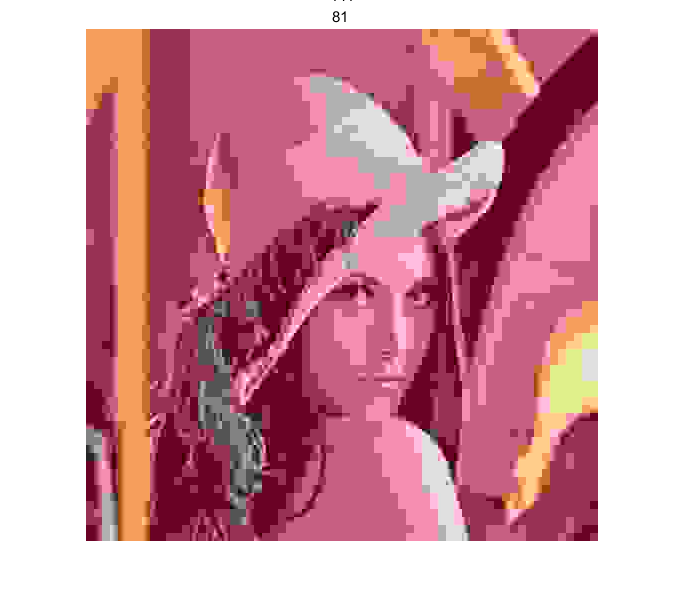

% RGB通道图像分别进行压缩 
R = I(:,:,1);
G = I(:,:,2);
B = I(:,:,3);
quality = [1,5,10,20];
RGB_ratio = [];
YCbCr_ratio = [];
RGB_rmse = [];
YCbCr_rmse = [];
for i = 1:4
    % RGB
    R_compress = im2jpeg(R,quality(i));
    G_compress = im2jpeg(G,quality(i));
    B_compress = im2jpeg(B,quality(i));
    
    R_recovery = jpeg2im(R_compress);
    G_recovery = jpeg2im(G_compress);
    B_recovery = jpeg2im(B_compress);
    I_c = cat(3,R_recovery,G_recovery,B_recovery);
    figure;
    imshow(I_c);
    title('RGB,quality=' + quality(i));
    RGB_ratio = [RGB_ratio,imratio(I,R_compress,G_compress,B_compress)];
    RGB_rmse = [RGB_rmse, CompareImages(I,I_c)];
    
    
    % YCbCr
    I_YCbCr = rgb2ycbcr(I);
    Y = I_YCbCr(:,:,1);
    Cb = imresize(I_YCbCr(:,:,2), 0.5);
    Cr = imresize(I_YCbCr(:,:,3), 0.5);
    Y_compress = im2jpeg(Y,quality(i));
    Cb_compress = im2jpeg(Cb,quality(i),1);
    Cr_compress = im2jpeg(Cr,quality(i),1);
    
    Y_recovery = jpeg2im(Y_compress);
    Cb_recovery = imresize(jpeg2im(Cb_compress,1), 2);
    Cr_recovery = imresize(jpeg2im(Cr_compress,1),2);
    
    I_c_y = ycbcr2rgb(cat(3,Y_recovery,Cb_recovery,Cr_recovery));
    figure;
    imshow(I_c_y);
    title('YCbCr,quality=' + quality(i));
    YCbCr_ratio = [YCbCr_ratio, imratio(I,Y_compress,Cb_compress,Cr_compress)];
    YCbCr_rmse = [YCbCr_rmse, CompareImages(I,I_c_y)];
end

RGB_ratio

RGB_ratio =     4.3487   17.7009   32.6931   61.3346


RGB_rmse

RGB_rmse =     4.7941    8.1274   11.1536   16.7867


YCbCr_ratio

YCbCr_ratio =    10.5860   42.4319   75.1703  131.3127


YCbCr_rmse

YCbCr_rmse =     6.6782   11.5532   16.7925   26.9367
